close all; clear all; clc;
digits(300);
addpath ./embedded
addpath ./mifiltertools
addpath ./utils
format LONGE

syms k integer;


fc=1000;
fp=907;
fs=1207;
Ap=0.1;
As=15;
fm=64000;

Fc=fc/fp;
Fp=fp/fp;
Fs=fs/fp;

[N,e]=mi_cheb1ord(Fc, Fs, Ap, As)

N =      6


e =      1.526204189509192e-01


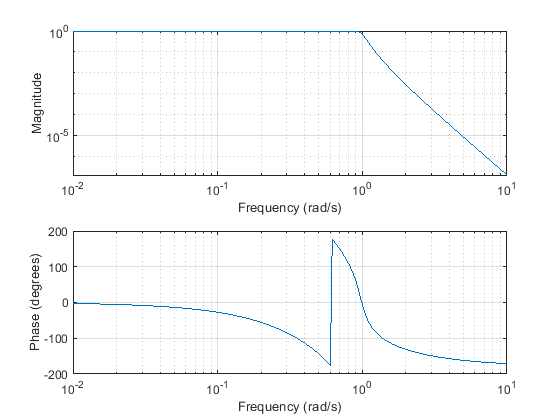




%%
syms k integer;
theta(k)=(2*k-1) / (2*N) *pi;

beta(k)=asinh((1)^k/e)/(N);
sk(k)=tanh(beta(k)).*(-1).*sin(theta(k)) + j*cos(theta(k));

AS=poly( double(sk(1:N)) );
BS=AS(end)/AS(1);
freqs(BS,AS);

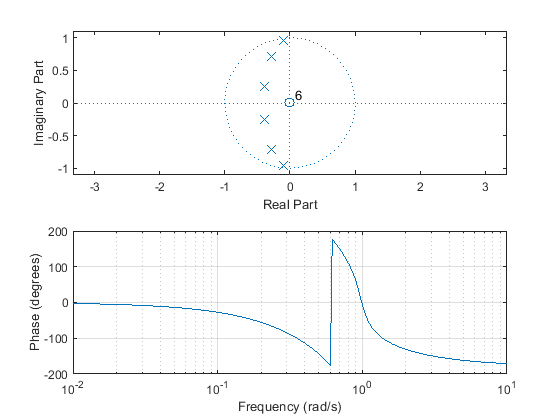

zplane( BS,AS )


%%
Bs=BS;
As=AS;
%[Bs, As] = lp2lp(BS, AS, 2*pi*fp);
freqs(Bs, As);

syms T;
[r,p,k]=residue(Bs,As);
pk=-(2+p*T)./(2-p*T);
rk=(r*T)./(2-r*T);

syms z;
H(z,T)=(1+z^-1)*sum(  rk./(1-pk*z^-1));
H(z)=collect(H(z,1));
[num(z),den(z)]=numden(H(z));
m=max( [abs(coeffs(num(z))),abs(coeffs(den(z)))])

$$m = 1.0793e+224$$

Bz=sym2poly(num(z)/m);
Az=sym2poly(den(z)/m);

[Bz,Az]=bilinear(Bs,As, 1)

Bz =     0.0007    0.0041    0.0102    0.0136    0.0102    0.0041    0.0007


Az =     1.0000   -3.6397    6.3108   -6.4241    4.0012   -1.4369    0.2322


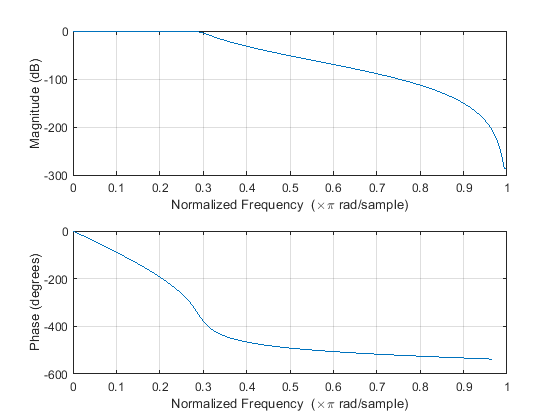

freqz(Bz,Az,1024);

[Bz,Az]=mi_bilinear_pk(Bs,As,1)

r =    0.1192 - 0.0287i
   0.1192 + 0.0287i
  -0.2679 + 0.2394i
  -0.2679 - 0.2394i
   0.1487 - 0.5237i
   0.1487 + 0.5237i


p =   -0.1049 + 0.9659i
  -0.1049 - 0.9659i
  -0.2865 + 0.7071i
  -0.2865 - 0.7071i
  -0.3913 + 0.2588i
  -0.3913 - 0.2588i



K =

     []



Bz =    0.2723 + 0.0000i   1.6339 - 0.0000i   4.0847 - 0.0000i   5.4463 + 0.0000i   4.0847 - 0.0000i   1.6339 - 0.0000i   0.2723 + 0.0000i


Az =     0.4002   -1.4567    2.5258   -2.5711    1.6014   -0.5751    0.0929





[Bz,Az]=mi_bilinear(Bs,As,1)

$$Hz(s) = \frac{7.0304e+15\,z^{6}+4.2182e+16\,z^{5}+1.0546e+17\,z^{4}+1.4061e+17\,z^{3}+1.0546e+17\,z^{2}+4.2182e+16\,z+7.0304e+15}{1.0333e+19\,z^{6}-3.7609e+19\,z^{5}+6.5209e+19\,z^{4}-6.6380e+19\,z^{3}+4.1344e+19\,z^{2}-1.4847e+19\,z+2.3994e+18}$$

Bz =     0.0001    0.0006    0.0016    0.0021    0.0016    0.0006    0.0001


Az =     0.1557   -0.5666    0.9824   -1.0000    0.6228   -0.2237    0.0361


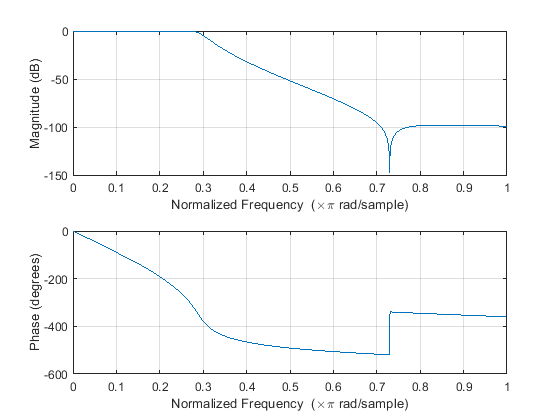


freqz(Bz,Az, 1024);

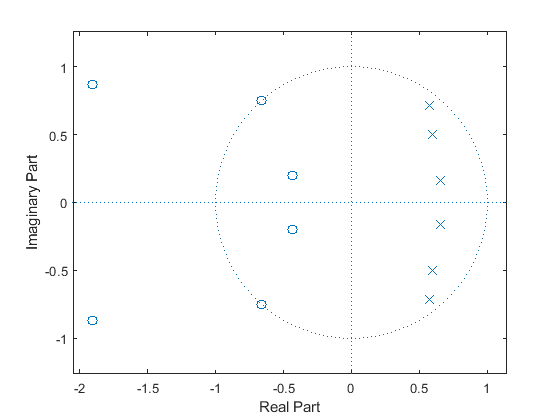


zplane( Bz, Az)